% load the running definition files exported from Peter's analysis pipeline
filepath2 = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/RunningRestingDefs/RunningDef_PeterRevised_20230723/'

filepath2 = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/RunningRestingDefs/RunningDef_PeterRevised_20230723/'

cd(filepath2)

Running_def_files = dir(filepath2)

Running_def_files = 17×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


Running_def_files(1:2) = [];
Running_def_files(13:end) = []

Running_def_files = 12×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



DataParameter_file = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/Pingchuan_RvR_Raw_files_delay_corrected/DataParameters20230115_no1611_2.csv'

DataParameter_file = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/Pingchuan_RvR_Raw_files_delay_corrected/DataParameters20230115_no1611_2.csv'

DataParameters = readtable(DataParameter_file,  'NumHeaderLines', 0)

DataParameters = 12×5 table
    MouseID    LaserPower            Basename                                                                          Path                                                                        Experiment        
    _______    __________    _________________________    ______________________________________________________________________________________________________________________________    _________________________

     1610          1         {'20220325_1610_RvR_001'}    {'/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/Pingchuan_RvR_Raw_files_no1627_length40/20220325_1610_RvR_001'}    {'20220325_1610_RvR_001'}
     1611          1         {'20220325_1611_RvR_001'}    {'/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/Pingchuan_RvR_Raw_files_no1627_length4

DataParameters_Basename = cell2mat(DataParameters.Basename);

animals = {};
lasers = {};
Running_durations_all = {};
Running_index_all = {};
Running_speed_median_all = {};
Speed_all = {};
Time_all = {};
RunningDef_all = {};
basename_all = {};

for i = 1:length(Running_def_files)
    Running_duration = [];
    RunningDef_individual_file = Running_def_files(i).name;
    animals{i} = RunningDef_individual_file(10:13);
    file_basename = RunningDef_individual_file(1:21);
    basename_all{i} = file_basename;

    % determine the laser power number
    for ii = 1:length(Running_def_files)
        if file_basename == DataParameters_Basename(ii,:)
            lasers{i} = num2str(DataParameters.LaserPower(ii));
        end
    end

    RunningDef_all_info = readtable(RunningDef_individual_file, 'NumHeaderLines', 1);
    RunningDef = table2array(RunningDef_all_info(:,4));
    RunningDef_all{i} = RunningDef;
    Speed = table2array(RunningDef_all_info(:,2));
    Speed_all{i} = Speed;
    Time_individual = table2array(RunningDef_all_info(:,1));
    Time_all{i} = Time_individual;

    Running_indexs = {};
    Running_speed_median = [];
    Running_index = [];
    Running_durations = [];
    Running_duration = 0;
    k = 1;

    for j = 1:length(RunningDef)

        if RunningDef(j) == 1
            Running_duration = Running_duration + 1;
            Running_index = [Running_index j];
        end

        if RunningDef(j) == 0
            if Running_duration > 0
                Running_indexs{k} = Running_index;
                k = k+1;
                Running_speed_median = [Running_speed_median median(abs(Speed(Running_index)))];
                Running_index = [];
                Running_durations = [Running_durations Running_duration];
                Running_duration = 0;
            end
        end
    end

    Running_durations_all{i} = Running_durations;
    Running_index_all{i} = Running_indexs;
    Running_speed_median_all{i} = Running_speed_median;

%     eval(['Running_indexs_', animals{i}, '_', lasers{i}, ' = Running_indexs;'])
%     eval(['Running_speed_median_', animals{i}, '_', lasers{i}, ' = Running_speed_median;'])
%     eval(['Running_durations_', animals{i}, '_', lasers{i}, ' = Running_durations;'])
%     

    
end

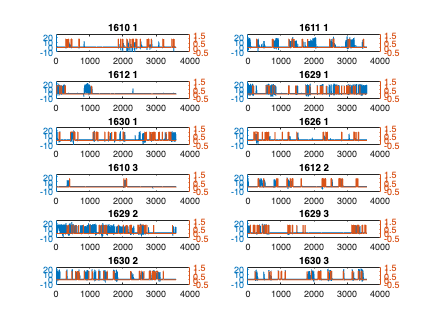

% plot the speed and running definitions for each recording

for i = 1:length(Running_def_files)
    subplot(6,2,i)
    yyaxis left
    plot(Time_all{i}, Speed_all{i},  'LineWidth', 1);
    ylim([-10 25])
    yyaxis right
    plot(Time_all{i}, RunningDef_all{i}, 'LineWidth', 1);
    ylim([-0.5 1.5])
    title([animals{i}, ' ', lasers{i}])

end

% the x axis labels for plotting
x_tick_labels = {};

for i = 1:length(Running_def_files)

    x_tick_labels{i} = [animals{i}, ' ', lasers{i}];
end


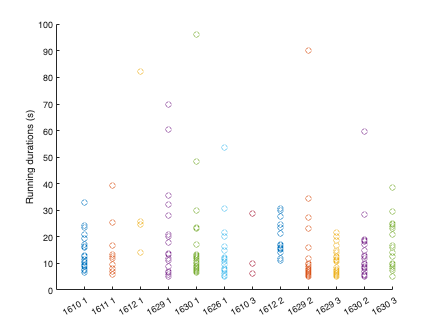

% plot running durations

running_durations_plot = NaN(50, 12);

figure
for i = 1:12

    scatter(zeros(1, length(Running_durations_all{i}))+i, Running_durations_all{i}*0.25)
    running_durations_plot(1:length(Running_durations_all{i}), i) = transpose(Running_durations_all{i}*0.25);
    hold on
end

xticks([1:1:12])
xticklabels(x_tick_labels)
ylabel('Running durations (s)')
hold off

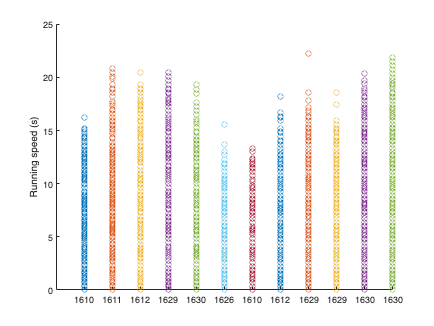

% plot running speed for each mice
running_speed_plot = NaN(2500, 12);

figure
for i = 1:12
    Running_speed_pooled = [];
    for j = 1:length(Running_index_all{i})
        Running_speed_pooled = [Running_speed_pooled; Speed_all{i}(Running_index_all{i}{j})];
    end

    running_speed_plot(1:length(Running_speed_pooled), i) = abs(Running_speed_pooled);

    scatter(zeros(1, length(Running_speed_pooled))+i, abs(Running_speed_pooled))
    hold on
end
xticks([1:1:12])
xticklabels(animals')
ylabel('Running speed (s)')
hold off

data_summary_csv = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/Pingchuan_RvR_Raw_files_delay_corrected/Scatter Plot (Raw)_grouped_PeterRevised_20230723.csv';
RvR_data_summary = readtable(data_summary_csv, 'NumHeaderLines', 1)

RvR_data_summary = 459×7 table
              Var1               Var2    Var3    Var4       Var5        Var6      Var7 
    _________________________    ____    ____    ____    __________    ______    ______

    {'20220325_1610_RvR_001'}    1610     1       0      3.7357e+05    2.4876    4.1805
    {'20220325_1610_RvR_001'}    1610     1       0       3.771e+05    2.4904    4.1823
    {'20220325_1610_RvR_001'}    1610     1       0      3.7982e+05    2.4931    4.1842
    {'20220325_1610_RvR_001'}    1610     1       0      3.8305e+05    2.5008     4.187
    {'20220325_1610_RvR_001'}    1610     1       0      3.8394e+05     2.501    4.1899
    {'20220325_1610_RvR_001'}    1610     1       0      3.8512e+05    2.5061    4.1937
    {'20220325_1610_RvR_00


Mouse_ID = table2array(RvR_data_summary(:,2))

Mouse_ID =         1610
        1610
        1610
        1610
        1610
        1610
        1610
        1610
        1610
        1610


Laser = table2array(RvR_data_summary(:,3))

Laser =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Speed = table2array(RvR_data_summary(:,4))

Speed =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


intensity = table2array(RvR_data_summary(:,5))/100000;
lft = table2array(RvR_data_summary(:,7))

lft =     4.1805
    4.1823
    4.1842
    4.1870
    4.1899
    4.1937
    4.1916
    4.1904
    4.1960
    4.1934


Mouse_ID_categorical = categorical(Mouse_ID)

Mouse_ID_categorical = 459×1 categorical array
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 


Laser_categorical = categorical(Laser);
States =  zeros(length(Speed),1);
Running_index = [];

for i = 1:length(Speed)
    if Speed(i,1) > 0
        States(i) = 1;
        Running_index = [Running_index i];
    end
end

States_categorical = categorical(States);

mouse_all = categories(Mouse_ID_categorical)

mouse_all = 6×1 cell array
    {'1610'}
    {'1611'}
    {'1612'}
    {'1626'}
    {'1629'}
    {'1630'}


laser_all = categories(Laser_categorical)

laser_all = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


States_all = categories(States_categorical)

States_all = 2×1 cell array
    {'0'}
    {'1'}


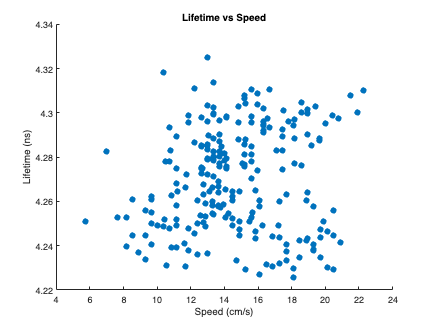

Speed_running = Speed(Running_index);
lft_running = lft(Running_index);

figure
scatter(Speed(Running_index), lft(Running_index), 50, 'filled')
xlabel('Speed (cm/s)')
ylabel('Lifetime (ns)')
title('Lifetime vs Speed')

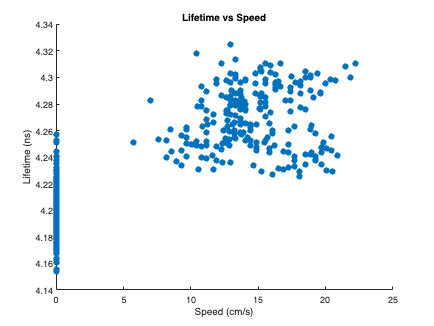


figure
scatter(Speed, lft, 50, 'filled')
xlabel('Speed (cm/s)')
ylabel('Lifetime (ns)')
title('Lifetime vs Speed')

lft_tbl = table(States_categorical, Mouse_ID_categorical, Laser_categorical, lft)

lft_tbl = 459×4 table
    States_categorical    Mouse_ID_categorical    Laser_categorical     lft  
    __________________    ____________________    _________________    ______

            0                     1610                    1            4.1805
            0                     1610                    1            4.1823
            0                     1610                    1            4.1842
            0                     1610                    1             4.187
            0                     1610                    1            4.1899
            0                     1610                    1            4.1937
            0                     1610                    1            4.1916
            0                     1610                    1            4.1904
            0                     1610                    1  

mdl1=stepwiseglm(lft_tbl,'constant', 'Upper', 'interactions','Criterion','adjrsquared')

1. Adding States_categorical, AdjRsquared = 0.73181
2. Adding Laser_categorical, AdjRsquared = 0.89796
3. Adding Mouse_ID_categorical, AdjRsquared = 0.91514
4. Adding Mouse_ID_categorical:Laser_categorical, AdjRsquared = 0.95112
5. Adding States_categorical:Mouse_ID_categorical, AdjRsquared = 0.95673


mdl1 = Generalized linear regression model:
    lft ~ 1 + States_categorical*Mouse_ID_categorical + Mouse_ID_categorical*Laser_categorical
    Distribution = Normal

Estimated Coefficients:
                                                       Estimate        SE         tStat        pValue  
                                                      __________    _________    ________    __________

    (Intercept)                                           4.1943    0.0017405      2409.7             0
    States_categorical_1                                0.060477    0.0022739      26.597    3.0447e-93
    Mouse_ID_categorical_1611                          0.0010261    0.0028479     0.36029        0.7188
    Mouse_ID_categorical_1612                         -0.0015986    0.0023096    -0.6

intensity_tbl = table(States_categorical, Mouse_ID_categorical, Laser_categorical, intensity)

intensity_tbl = 459×4 table
    States_categorical    Mouse_ID_categorical    Laser_categorical    intensity
    __________________    ____________________    _________________    _________

            0                     1610                    1             3.7357  
            0                     1610                    1              3.771  
            0                     1610                    1             3.7982  
            0                     1610                    1             3.8305  
            0                     1610                    1             3.8394  
            0                     1610                    1             3.8512  
            0                     1610                    1             3.8393  
            0                     1610                    1             3.8181  
            0            

mdl2=stepwiseglm(intensity_tbl,'constant', 'Upper','Linear','Criterion','adjrsquared')

1. Adding Mouse_ID_categorical, AdjRsquared = 0.58992
2. Adding Laser_categorical, AdjRsquared = 0.88327
3. Adding States_categorical, AdjRsquared = 0.91131


mdl2 = Generalized linear regression model:
    intensity ~ 1 + States_categorical + Mouse_ID_categorical + Laser_categorical
    Distribution = Normal

Estimated Coefficients:
                                 Estimate       SE        tStat       pValue   
                                 ________    ________    _______    ___________

    (Intercept)                   4.1345     0.055304     74.761    7.0006e-256
    States_categorical_1         0.51681     0.043132     11.982     6.6352e-29
    Mouse_ID_categorical_1611    -2.3305     0.095705    -24.351     3.6178e-84
    Mouse_ID_categorical_1612     1.2927     0.074336      17.39     3.4815e-52
    Mouse_ID_categorical_1626    -1.4948     0.081598    -18.319     2.0518e-56
    Mouse_ID_categorical_1629

intensity_collection=[];
lft_collection=[];
mouseID_collection=[];
laser_collection=[];
states_collection=[];

for i=1:6
    mouse=mouse_all(i)
    

    lft_mouse=lft(find(Mouse_ID_categorical == mouse));
    intensity_mouse=intensity(find(Mouse_ID_categorical == mouse));
    speed_mouse=Speed(find(Mouse_ID_categorical == mouse));
    laser_mouse=Laser(find(Mouse_ID_categorical == mouse));
    states_mouse=States(find(Mouse_ID_categorical == mouse));

    eval(['lft_',convertStringsToChars(cell2mat(mouse)),'=lft_mouse;'])
    eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'=intensity_mouse;'])
    eval(['speed_',convertStringsToChars(cell2mat(mouse)),'=speed_mouse;'])
    eval(['laser_',convertStringsToChars(cell2mat(mouse)),'=laser_mouse;'])
    eval(['states_',convertStringsToChars(cell2mat(mouse)),'=states_mouse;'])

    for j=1:3

        lft_mouse_laser=lft_mouse(find(laser_mouse==j));
        intensity_mouse_laser=intensity_mouse(find(laser_mouse==j));
        speed_mouse_laser=speed_mouse(find(laser_mouse==j));
        states_mouse_laser=states_mouse(find(laser_mouse==j));
        lft_mouse_laser_running=lft_mouse_laser(find(states_mouse_laser==1));
        lft_mouse_laser_resting=lft_mouse_laser(find(states_mouse_laser==0));
        intensity_mouse_laser_running=intensity_mouse_laser(find(states_mouse_laser==1));

        mouseID_collection=[mouseID_collection;str2num(cell2mat(mouse))];
        laser_collection=[laser_collection;j];
        states_collection=[states_collection;[1]];
        if isempty(intensity_mouse_laser_running)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_running)];
        end

        if isempty(lft_mouse_laser_running)
            lft_collection=[lft_collection;[NaN]];
        else
            lft_collection=[lft_collection;mean(lft_mouse_laser_running)];
        end

        intensity_mouse_laser_resting=intensity_mouse_laser(find(states_mouse_laser==0));

        mouseID_collection=[mouseID_collection;str2num(cell2mat(mouse))];
        laser_collection=[laser_collection;[j]];
        states_collection=[states_collection;[0]];
        if isempty(intensity_mouse_laser_resting)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_resting)];
        end

        if isempty(lft_mouse_laser_resting)
            lft_collection=[lft_collection;[NaN]];
        else
            lft_collection=[lft_collection;mean(lft_mouse_laser_resting)];
        end

      
        

        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=lft_mouse_laser;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=intensity_mouse_laser;'])
        eval(['speed_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=speed_mouse_laser;'])
        eval(['states_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=states_mouse_laser;'])

        lft_mouse_laser_running = [lft_mouse_laser_running;NaN(100-length(lft_mouse_laser_running), 1)];
        lft_mouse_laser_resting = [lft_mouse_laser_resting;NaN(100-length(lft_mouse_laser_resting), 1)];
        intensity_mouse_laser_running = [intensity_mouse_laser_running;NaN(100-length(intensity_mouse_laser_running), 1)];
        intensity_mouse_laser_resting = [intensity_mouse_laser_resting;NaN(100-length(intensity_mouse_laser_resting), 1)];
        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_running','=lft_mouse_laser_running;'])
        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_resting','=lft_mouse_laser_resting;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_running','=intensity_mouse_laser_running;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_resting','=intensity_mouse_laser_resting;'])
    end

end

mouse = 1×1 cell array
    {'1610'}


mouse = 1×1 cell array
    {'1611'}


mouse = 1×1 cell array
    {'1612'}


mouse = 1×1 cell array
    {'1626'}


mouse = 1×1 cell array
    {'1629'}


mouse = 1×1 cell array
    {'1630'}


lft_running_all = {};
intensity_running_all = {};
running_epoch_nums_signals = [];
running_epoch_nums_speed = [];

for i = 1:12
    eval(['lft_running = lft_', animals{i}, '_', lasers{i}, '_running;'])
    eval(['intensity_running = intensity_', animals{i}, '_', lasers{i}, '_running;'])
    lft_running(isnan(lft_running)) = [];
    intensity_running(isnan(intensity_running)) = [];
    running_epoch_nums_signals = [running_epoch_nums_signals; length(lft_running)];
    running_epoch_nums_speed = [running_epoch_nums_speed; length(Running_durations_all{i})];
    lft_running_all{i} = lft_running;
    intensity_running_all{i} = intensity_running;
end

running_epoch_nums_signals

running_epoch_nums_signals =     23
    13
     4
    25
    30
    21
     3
    17
    27
    29


running_epoch_nums_speed

running_epoch_nums_speed =     23
    13
     4
    25
    30
    21
     3
    17
    27
    29


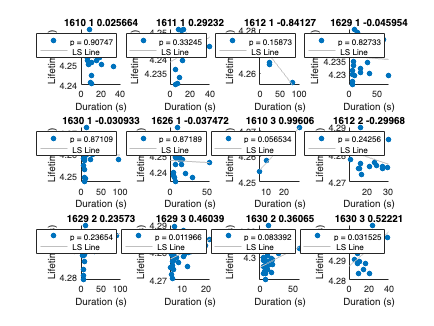

% Plot the correlation between running duration and lifetime, for each
% individual recording
corr_coeffs_all = {};
p_values_all = {};
for i = 1:12

    [R,P] = corrcoef(transpose(Running_durations_all{i}), lft_running_all{i});
    corr_coeffs_all{i} = R;
    p_values_all{i} = P;

    subplot(3,4,i)
    scatter(transpose(Running_durations_all{i}*0.25), lft_running_all{i}, 'filled')
    title([animals{i}, ' ', lasers{i}, ' ', num2str(R(1,2))])
    ylabel('Lifetime (ns)')
    xlabel('Duration (s)')
    lsline
    legend({['p = ', num2str(P(1,2))], ' LS Line'})
end

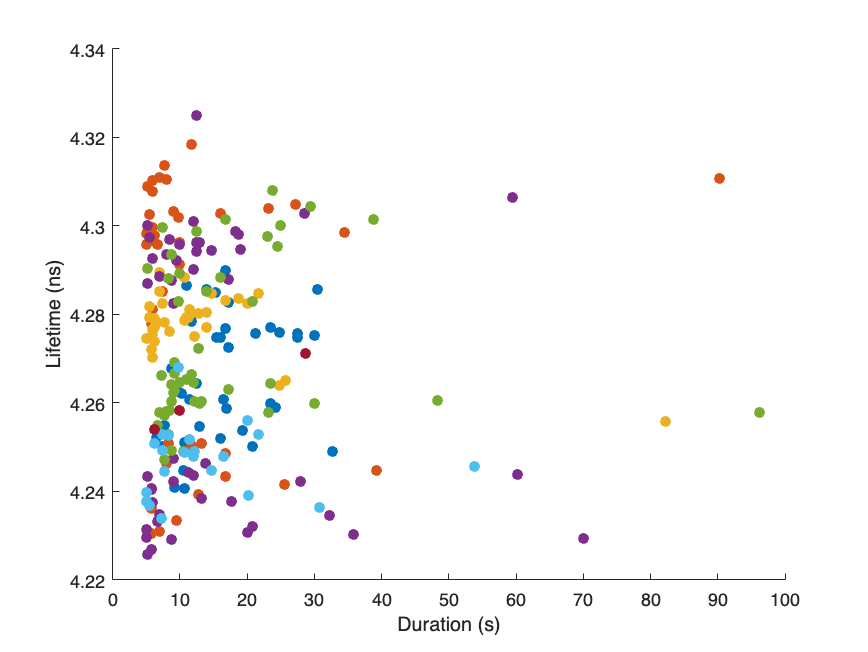

% Plot the correlation between running duration and lifetime, for each
% individual recording
% duration_plot_pooled can be copied and pasted directly into prism for
% plotting

Color_options = {"red", "green", "blue", "cyan", "magenta", "yellow", "black", [0 0.4470 0.7410], ...
    [0.8500 0.3250 0.0980], [0.9290 0.6940 0.1250], [0.4940 0.1840 0.5560], [0.4660 0.6740 0.1880]};

Running_epoch_nums = 0;

figure

for i = 1:12

    scatter(transpose(Running_durations_all{i}*0.25), lft_running_all{i}, 'filled', 'ColorVariable',Color_options{i})
    Running_epoch_nums = [Running_epoch_nums Running_epoch_nums(i) + length(lft_running_all{i})];
    hold on
end

ylabel('Lifetime (ns)')
xlabel('Duration (s)')
hold off


duration_plot_pooled = NaN(Running_epoch_nums(end), 13);

for i = 1:12
    duration_plot_pooled(Running_epoch_nums(i)+1:Running_epoch_nums(i+1),1) = transpose(Running_durations_all{i}*0.25);
    duration_plot_pooled(Running_epoch_nums(i)+1:Running_epoch_nums(i+1),i+1) = transpose(lft_running_all{i});

end

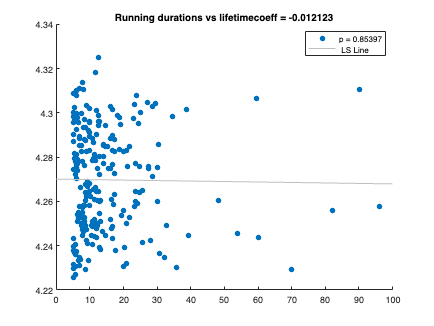

% pool together, plot the correlation between running duration and lifetime
lft_running_pooled = [];
intensity_running_pooled = [];
running_durations_pooled = [];

for i = 1:12
    lft_running_pooled = [lft_running_pooled;lft_running_all{i}];
    intensity_running_pooled = [intensity_running_pooled;intensity_running_all{i}];
    running_durations_pooled = [running_durations_pooled; transpose(Running_durations_all{i}*0.25)];
  
end

[R_pooled,P_pooled] = corrcoef(running_durations_pooled, lft_running_pooled);
figure
scatter(running_durations_pooled, lft_running_pooled, 'filled')
title(['Running durations vs lifetime', 'coeff = ', num2str(R_pooled(1,2))])
lsline
legend({['p = ', num2str(P_pooled(1,2))], ' LS Line'})

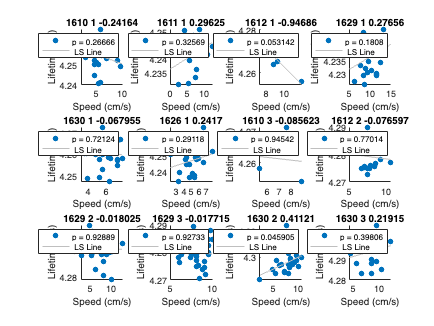

% Plot the correlation between running speed median and lifetime, for each
% individual recording
corr_coeffs_all = {};
p_values_all = {};
for i = 1:12

    [R,P] = corrcoef(transpose(Running_speed_median_all{i}), lft_running_all{i});
    corr_coeffs_all{i} = R;
    p_values_all{i} = P;

    subplot(3,4,i)
    scatter(transpose(Running_speed_median_all{i}), lft_running_all{i}, 'filled')
    ylabel('Lifetime (ns)')
    xlabel('Speed (cm/s)')
    title([animals{i}, ' ', lasers{i}, ' ', num2str(R(1,2))])
    lsline
    legend({['p = ', num2str(P(1,2))], ' LS Line'})
end

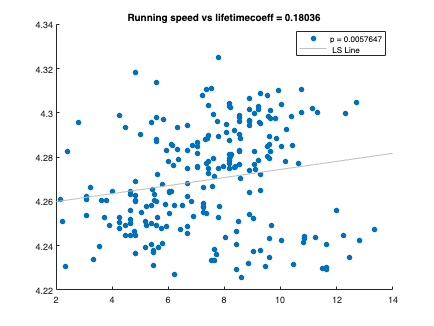

% pool together, plot the correlation between running duration and lifetime
lft_running_pooled = [];
running_speed_pooled = [];
lft_running_animal_label = [];
lft_running_laser_lablel = [];

for i = 1:12
    lft_running_pooled = [lft_running_pooled;lft_running_all{i}];
    running_speed_pooled = [running_speed_pooled; transpose(Running_speed_median_all{i})];
    lft_running_animal_label = [lft_running_animal_label; repmat(convertCharsToStrings(animals{i}), length(lft_running_all{i}), 1)];
    lft_running_laser_lablel = [lft_running_laser_lablel; repmat(convertCharsToStrings(lasers{i}), length(lft_running_all{i}), 1)];

  
end

[R_pooled,P_pooled] = corrcoef(running_speed_pooled, lft_running_pooled);
figure
scatter(running_speed_pooled, lft_running_pooled, 'filled')
title(['Running speed vs lifetime', 'coeff = ', num2str(R_pooled(1,2))])
lsline
legend({['p = ', num2str(P_pooled(1,2))], ' LS Line'})

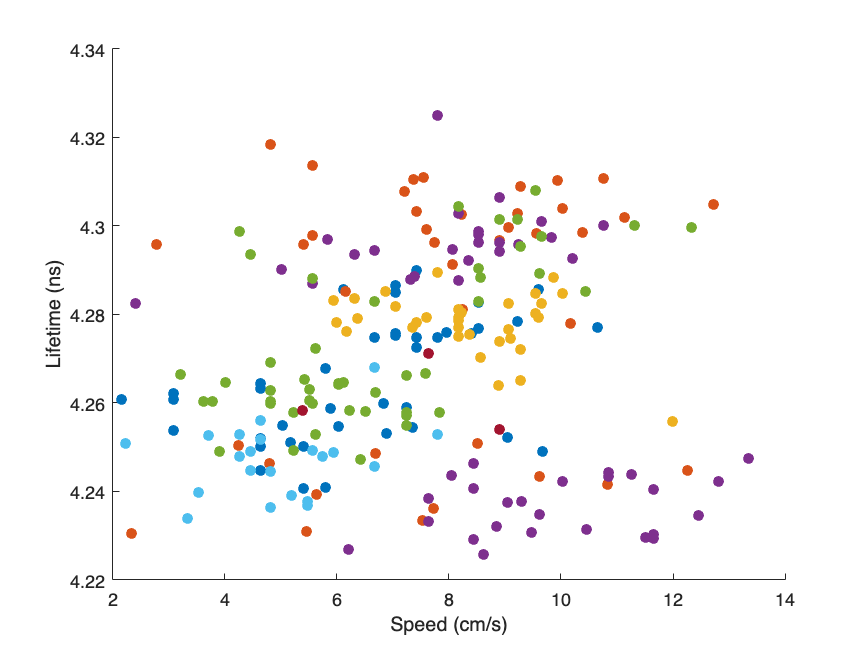

% for pooling all the lifetime and running speed together
% speed_plot_pooled can be copied and pasted directly into prism for
% plotting

Color_options = {"red", "green", "blue", "cyan", "magenta", "yellow", "black", [0 0.4470 0.7410], ...
    [0.8500 0.3250 0.0980], [0.9290 0.6940 0.1250], [0.4940 0.1840 0.5560], [0.4660 0.6740 0.1880]};
Running_epoch_nums = 0;
figure

for i = 1:12

    scatter(transpose(Running_speed_median_all{i}), lft_running_all{i}, 'filled', 'ColorVariable',Color_options{i})
    Running_epoch_nums = [Running_epoch_nums Running_epoch_nums(i) + length(lft_running_all{i})];
    hold on
end

ylabel('Lifetime (ns)')
xlabel('Speed (cm/s)')
hold off


speed_plot_pooled = NaN(Running_epoch_nums(end), 13);

for i = 1:12
    speed_plot_pooled(Running_epoch_nums(i)+1:Running_epoch_nums(i+1),1) = transpose(Running_speed_median_all{i});
    speed_plot_pooled(Running_epoch_nums(i)+1:Running_epoch_nums(i+1),i+1) = transpose(lft_running_all{i});

end

% GLM analysis, use animal ID and laser as categorical variables
lft_running_animal_label = categorical(lft_running_animal_label);
lft_running_laser_lablel = categorical(lft_running_laser_lablel);

% GLM analysis: dependent: lifetime; independent: running speed, aninmal,
% laser
running_speed_lft_tbl = table(running_speed_pooled, lft_running_animal_label, lft_running_laser_lablel, lft_running_pooled);

fitglm(running_speed_lft_tbl)

ans = Generalized linear regression model:
    lft_running_pooled ~ 1 + running_speed_pooled + lft_running_animal_label + lft_running_laser_lablel
    Distribution = Normal

Estimated Coefficients:
                                      Estimate         SE         tStat       pValue  
                                     ___________    _________    _______    __________

    (Intercept)                           4.2537     0.002774     1533.4             0
    running_speed_pooled             -0.00036266    0.0003431     -1.057       0.29165
    lft_running_animal_label_1611     -0.0090204    0.0034715    -2.5984     0.0099866
    lft_running_animal_label_1612      -0.010348     0.003371    -3.0697     0.0024073
    lft_running_animal_label_1626     -0.0049822    0.0029

% GLM analysis: dependent: lifetime; independent: running duration, aninmal,
% laser
running_duration_lft_tbl = table(running_durations_pooled, lft_running_animal_label, lft_running_laser_lablel, lft_running_pooled);

fitglm(running_duration_lft_tbl)

ans = Generalized linear regression model:
    lft_running_pooled ~ 1 + running_durations_pooled + lft_running_animal_label + lft_running_laser_lablel
    Distribution = Normal

Estimated Coefficients:
                                      Estimate         SE         tStat       pValue  
                                     __________    __________    _______    __________

    (Intercept)                          4.2506     0.0021125     2012.1             0
    running_durations_pooled         7.8897e-05    5.1697e-05     1.5261       0.12839
    lft_running_animal_label_1611     -0.009579     0.0034186    -2.8021     0.0055224
    lft_running_animal_label_1612     -0.012167     0.0033214    -3.6632    0.00031089
    lft_running_animal_label_1626    -0.0047162     0.

% calculate the transition triggered change
datapath_all = {};

for i = 1:12
    datapath_all{i} = ['/Volumes/PcSSDA/RvR/', basename_all{i}, '/'];
end
   

ExperimentalName_all = {};
for i = 1:12
    ExperimentalName_all{i} = basename_all{i};
end

analysis_postfix = ...
    {'20220403.mat',...
    '20220403.mat',...
    '20220403.mat',...
    '20220512.mat',...
    '20220512.mat',...
    '20220403.mat',...
    '20220403.mat',...
    '20220403.mat',...
    '20220512.mat',...
    '20220512.mat',...
    '20220512.mat',...
    '20220512.mat'...
    }

analysis_postfix = 1×12 cell array
    {'20220403.mat'}    {'20220403.mat'}    {'20220403.mat'}    {'20220512.mat'}    {'20220512.mat'}    {'20220403.mat'}    {'20220403.mat'}    {'20220403.mat'}    {'20220512.mat'}    {'20220512.mat'}    {'20220512.mat'}    {'20220512.mat'}


% trim the running index
Running_index_trimmed_all = {};

for i = 1:12

    for j = 1:length(Running_index_all{i})
        Running_index_trimmed = Running_index_all{i}{j};
        Running_index_trimmed(1:12) = []; % 3 seconds of trimming at the beginning of the runnin epoch
        Running_index_trimmed_all{i}{j} = Running_index_trimmed;
    end
end

baseline_start_length = [-10 -5]; % 5s for baseline start
baseline_end_length = [-5 0]; % 5s for baseline end

median_running_all = {};
median_baselineStart_all = {};
median_baselineEnd_all = {};

median_running_intensity_all = {};
median_baselineStart_intensity_all = {};
median_baselineEnd_intensity_all = {};


mkdir('RunningEpochTransitions')



for i = 1:12

    analysis_file_name = [datapath_all{i}, ExperimentalName_all{i}, '_analysis_1_', analysis_postfix{i}]
    load(analysis_file_name)
    time =  time - Speed_time_shift_all(i);

    speed = Speed_all{i};
    speedTime = Time_all{i};
    Running_Def_trimmed = zeros(1,length(speedTime))-5;

    for k = 1:length(Running_index_trimmed_all{i})
        Running_Def_trimmed(Running_index_trimmed_all{i}{k}) = 20;
    end


    Running_Def_index_trimmed = Running_index_trimmed_all{i};
    Running_Def_index = Running_index_all{i};

    median_running_plot = [];
    median_running = [];
    median_time = [];
    median_baselineStart = [];
    median_baselineEnd = [];

    median_running_intensity_plot = [];
    median_running_intensity = [];
    median_time = [];
    median_baselineStart_intensity = [];
    median_baselineEnd_intensity = [];


    for j = 1:length(Running_Def_index_trimmed)
%         epoch_start_FLP = min(find(time >= speedTime(Running_Def_index{j}(1))));
%         epoch_end_FLP = max(find(time <= speedTime(Running_Def_index{j}(end))));

        % find the index for FLP data corresponding to running epoch,
        % calculate the median of running epoch

%         time_diff_start = abs(time - speedTime(Running_Def_index_trimmed{j}(1)));
%         epoch_start_FLP_trimmed = find(time_diff_start == min(time_diff_start));

%         time_diff_end = abs(time - speedTime(Running_Def_index_trimmed{j}(end)));
%         epoch_end_FLP_trimmed = find(time_diff_end == min(time_diff_end));

        epoch_start_FLP_trimmed = FindNearestIndex(time, speedTime(Running_Def_index_trimmed{j}(1)));
        epoch_end_FLP_trimmed = FindNearestIndex(time, speedTime(Running_Def_index_trimmed{j}(end)));

        FLP_this_epoch = tau_empTrunc(epoch_start_FLP_trimmed:epoch_end_FLP_trimmed);
        intensity_this_epoch = photoncount(epoch_start_FLP_trimmed:epoch_end_FLP_trimmed);
        median_running = [median_running median(FLP_this_epoch)];
        median_running_intensity = [median_running_intensity median(intensity_this_epoch)];

        % To plot the mdian point, find the median point index
        [this_median_index, this_median] = FindMedianIndex(FLP_this_epoch, epoch_start_FLP_trimmed);
        median_time = [median_time this_median_index];
        median_running_plot = [median_running_plot this_median];

        [this_median_index_intensity, this_median_intensity] = FindMedianIndex(intensity_this_epoch, epoch_start_FLP_trimmed);
        median_running_intensity_plot = [median_running_intensity_plot this_median_intensity];

        % find the index for FLP data corresponding to baseline end,
        % calculate the median of running epoch

%         time_diff_start = abs(time - speedTime(Running_Def_index{j}(1))-baseline_end_length(1));
%         baseline_end_FLP_1 = find(time_diff_start == min(time_diff_start));
% 
%         time_diff_end = abs(time - speedTime(Running_Def_index{j}(1))-baseline_end_length(2));
%         baseline_end_FLP_2 = find(time_diff_end == min(time_diff_end));

        baseline_end_FLP_1 = FindNearestIndex(time, speedTime(Running_Def_index{j}(1)) + baseline_end_length(1));
        baseline_end_FLP_2 = FindNearestIndex(time, speedTime(Running_Def_index{j}(1)) + baseline_end_length(2));

        FLP_baseline_end = tau_empTrunc(baseline_end_FLP_1:baseline_end_FLP_2);
        intensity_baseline_end = photoncount(baseline_end_FLP_1:baseline_end_FLP_2);

        median_baselineEnd = [median_baselineEnd median(FLP_baseline_end)];
        median_baselineEnd_intensity = [median_baselineEnd_intensity median(intensity_baseline_end)];

        [median_index_BE, median_BE_plot] = FindMedianIndex(FLP_baseline_end, baseline_end_FLP_1);
        [median_index_BE_intensity, median_BE_intensity_plot] = FindMedianIndex(intensity_baseline_end, baseline_end_FLP_1);

        % find the index for FLP data corresponding to baseline start,
        % calculate the median of running epoch

%         time_diff_start = abs(time - speedTime(Running_Def_index{j}(1))-baseline_start_length(1));
%         baseline_start_FLP_1 = find(time_diff_start == min(time_diff_start));
% 
%         time_diff_end = abs(time - speedTime(Running_Def_index{j}(1))-baseline_start_length(2));
%         baseline_start_FLP_2 = find(time_diff_end == min(time_diff_end));

        baseline_start_FLP_1 = FindNearestIndex(time, speedTime(Running_Def_index{j}(1))+baseline_start_length(1));
        baseline_start_FLP_2 = FindNearestIndex(time, speedTime(Running_Def_index{j}(1))+baseline_start_length(2));

        FLP_baseline_start = tau_empTrunc(baseline_start_FLP_1:baseline_start_FLP_2);
        median_baselineStart = [median_baselineStart median(FLP_baseline_start)];

        [median_index_BS, median_BS_plot] = FindMedianIndex(FLP_baseline_start, baseline_start_FLP_1);

        intensity_baseline_start = photoncount(baseline_start_FLP_1:baseline_start_FLP_2);
        median_baselineStart_intensity = [median_baselineStart_intensity median(intensity_baseline_start)];

        [median_index_BS_intensity, median_BS_intensity_plot] = FindMedianIndex(intensity_baseline_start, baseline_start_FLP_1);

        figure0 = figure('visible','off');
        figure0.Position=[10 10 1000 400];
        yyaxis left
        plot(time(baseline_start_FLP_1:epoch_end_FLP_trimmed), tau_empTrunc(baseline_start_FLP_1:epoch_end_FLP_trimmed))
        hold on
        scatter(time(median_index_BS), median_BS_plot, 'filled')
        hold on
        scatter(time(median_index_BE), median_BE_plot, 'filled')
        hold on
        scatter(time(this_median_index), this_median, 'filled')
        ylabel('Lifetime (ns)')
        xlabel('Time (s)')
%         xline([time(baseline_start_FLP_1) time(baseline_start_FLP_1)+5 time(baseline_start_FLP_1)+10 time(baseline_start_FLP_1)+13 time(epoch_end_FLP_trimmed)])
        title([animals{i}, ' ', lasers{i}, ' ', num2str(j), 'th running eopch'])
        hold off
        yyaxis right
        plot(speedTime(Running_Def_index_trimmed{j}(1)-13*4:Running_Def_index_trimmed{j}(end)), speed(Running_Def_index_trimmed{j}(1)-13*4:Running_Def_index_trimmed{j}(end)))
        ylabel('Speed (cm/s)')
        yline([-1 1])
        xline([speedTime(Running_Def_index{j}(1))+baseline_start_length(1) speedTime(Running_Def_index{j}(1))+baseline_start_length(2) speedTime(Running_Def_index{j}(1)) speedTime(Running_Def_index_trimmed{j}(1)) speedTime(Running_Def_index_trimmed{j}(end))])
        SavedRunningEpochPlotName = ['RunningEpochTransitions/', animals{i}, '_', lasers{i}, '_', num2str(j), '_running.png'];
        saveas(gcf, SavedRunningEpochPlotName)

        figure1 = figure('visible','off');
        figure1.Position=[10 10 1000 400];
        yyaxis left
        plot(time(baseline_start_FLP_1:epoch_end_FLP_trimmed), photoncount(baseline_start_FLP_1:epoch_end_FLP_trimmed))
        hold on
        scatter(time(median_index_BS_intensity), median_BS_intensity_plot, 'filled')
        hold on
        scatter(time(median_index_BE_intensity), median_BE_intensity_plot, 'filled')
        hold on
        scatter(time(this_median_index_intensity), this_median_intensity, 'filled')
        ylabel('Intensity')
        xlabel('Time (s)')
%         xline([time(baseline_start_FLP_1) time(baseline_start_FLP_1)+5 time(baseline_start_FLP_1)+10 time(baseline_start_FLP_1)+13 time(epoch_end_FLP_trimmed)])
        title([animals{i}, ' ', lasers{i}, ' ', num2str(j), 'th running eopch intensity'])
        hold off
        yyaxis right
        plot(speedTime(Running_Def_index_trimmed{j}(1)-13*4:Running_Def_index_trimmed{j}(end)), speed(Running_Def_index_trimmed{j}(1)-13*4:Running_Def_index_trimmed{j}(end)))
        ylabel('Speed (cm/s)')
        yline([-1 1])
        xline([speedTime(Running_Def_index{j}(1))+baseline_start_length(1) speedTime(Running_Def_index{j}(1))+baseline_start_length(2) speedTime(Running_Def_index{j}(1)) speedTime(Running_Def_index_trimmed{j}(1)) speedTime(Running_Def_index_trimmed{j}(end))])
        SavedRunningEpochPlotName = ['RunningEpochTransitions/Intensity_', animals{i}, '_', lasers{i}, '_', num2str(j), '_running.png'];
        saveas(gcf, SavedRunningEpochPlotName)



%         [med,I]=sort(FLP_this_epoch);
%         if rem(size(FLP_this_epoch),2)==1
%             this_median_index =I((size(FLP_this_epoch,1)+1)/2)+epoch_start_FLP_trimmed-1;
%             median_running_plot = [median_running_plot median(FLP_this_epoch)];
%         else
%             this_median_index = [I(size(FLP_this_epoch,1)/2) I(size(FLP_this_epoch,1)/2+1)]+epoch_start_FLP_trimmed-1;
%             median_running_plot = [median_running_plot median(FLP_this_epoch) median(FLP_this_epoch)];
%         end
%         median_time = [median_time this_median_index];
    end

    
    

    median_running_all{i} = median_running;
    median_baselineStart_all{i} = median_baselineStart;
    median_baselineEnd_all{i} = median_baselineEnd;


    median_running_intensity_all{i} = median_running_intensity;
    median_baselineStart_intensity_all{i} = median_baselineStart_intensity;
    median_baselineEnd_intensity_all{i} = median_baselineEnd_intensity;
% 
%     for l = 1:3
% 
%         figure1=figure('visible','off');
%         figure1.Position=[10 10 3500 600];
%         yyaxis left
%         plot(time, tau_empTrunc, 'LineWidth', 2)
%         hold on
%         scatter(time(median_time), median_running_plot, 60, 'filled', 'red')
%         ylabel('Lifetime (ns)')
%         xlabel('Time (s)')
%     %     ylim([4.15 4.30])
%         yyaxis right
%         plot(speedTime, speed, 'Color', 'k', 'LineWidth', 2)
%         hold on
%         plot(speedTime, Running_Def_trimmed, 'LineWidth', 2)
%         ylabel('Speed (cm/s)')
%         ylim([-10 25])
%         yticks([-10 0 10 20])
%         xlim([(l-1)*1200 (l-1)*1200+1200])
% %         xlim([270 400])
%         title([animals{i}, ' ', lasers{i}, ' (', num2str(l), ')'])
%         figure_name_fig = [animals{i}, '_', lasers{i}, '_(', num2str(l), ').fig'];
%         figure_name_png = [animals{i}, '_', lasers{i}, '_(', num2str(l), ').png'];
% %         saveas(gcf, figure_name_fig)
% %         saveas(gcf, figure_name_png)

%     end

end

analysis_file_name = '/Volumes/PcSSDA/RvR/20220325_1610_RvR_001/20220325_1610_RvR_001_analysis_1_20220403.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220325_1611_RvR_001/20220325_1611_RvR_001_analysis_1_20220403.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220325_1612_RvR_001/20220325_1612_RvR_001_analysis_1_20220403.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220328_1629_RvR_001/20220328_1629_RvR_001_analysis_1_20220512.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220328_1630_RvR_001/20220328_1630_RvR_001_analysis_1_20220512.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220329_1626_RvR_001/20220329_1626_RvR_001_analysis_1_20220403.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220330_1610_RvR_003/20220330_1610_RvR_003_analysis_1_20220403.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220330_1612_RvR_002/20220330_1612_RvR_002_analysis_1_20220403.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220404_1629_RvR_002/20220404_1629_RvR_002_analysis_1_20220512.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220404_1629_RvR_003/20220404_1629_RvR_003_analysis_1_20220512.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220404_1630_RvR_002/20220404_1630_RvR_002_analysis_1_20220512.mat'

analysis_file_name = '/Volumes/PcSSDA/RvR/20220404_1630_RvR_003/20220404_1630_RvR_003_analysis_1_20220512.mat'

        

% 
% speed_1610 = Speed_all{1};
% speedTime_1610 = Time_all{i};
% RunningDef_1610 = RunningDef_all{i};
% RunningDef_1610(find(RunningDef_1610 == 0)) = -5;
% RunningDef_1610(find(RunningDef_1610 == 1)) = 20;
% RunningEpoch_1610_start = Running_index_start_all{1}*0.25;
% RuningDuration_1610 = Running_durations_all{i}*0.25;

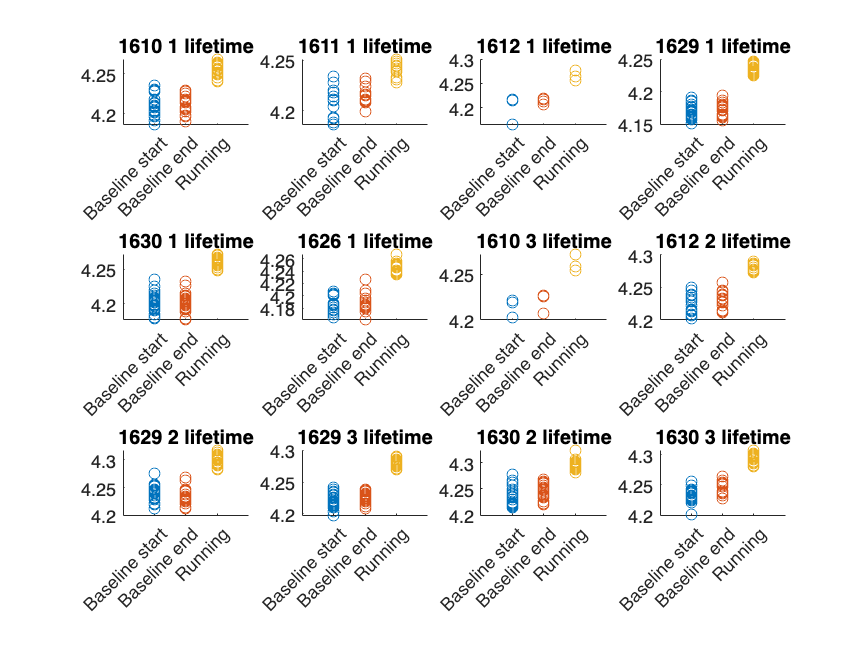

for i = 1:12
    subplot(3,4,i)
%     figure
    scatter(zeros(1, length(median_running_all{i}))+1, median_baselineStart_all{i})
    hold on
    scatter(zeros(1, length(median_running_all{i}))+2, median_baselineEnd_all{i})
    hold on
    scatter(zeros(1, length(median_running_all{i}))+3, median_running_all{i})
    xlim([0 4])
    xticks([1 2 3])
    xticklabels({'Baseline start', 'Baseline end', 'Running'})
    title([animals{i}, ' ', lasers{i}, ' lifetime'])
    hold off
end

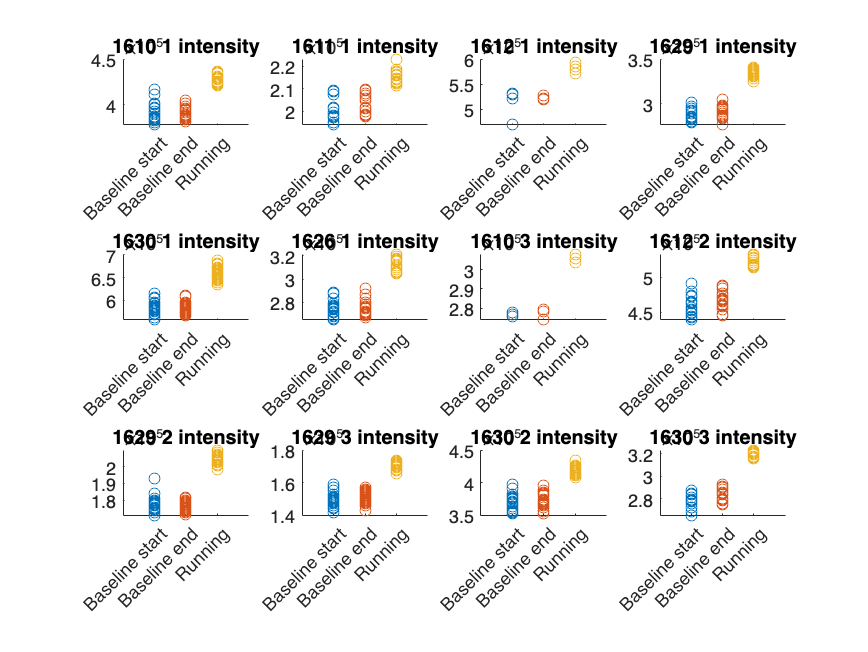

for i = 1:12
    subplot(3,4,i)
%     figure
    scatter(zeros(1, length(median_running_intensity_all{i}))+1, median_baselineStart_intensity_all{i})
    hold on
    scatter(zeros(1, length(median_running_intensity_all{i}))+2, median_baselineEnd_intensity_all{i})
    hold on
    scatter(zeros(1, length(median_running_intensity_all{i}))+3, median_running_intensity_all{i})
    xlim([0 4])
    xticks([1 2 3])
    xticklabels({'Baseline start', 'Baseline end', 'Running'})
    title([animals{i}, ' ', lasers{i}, ' intensity'])
    hold off
end

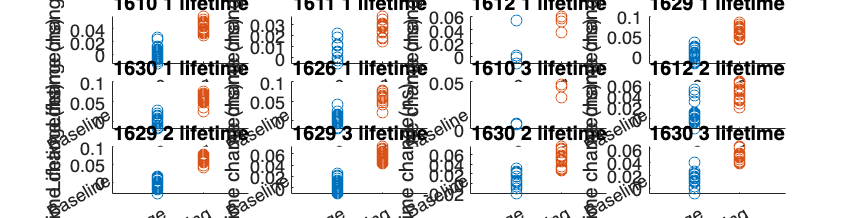

baseline_change_pooled_lft = [];
running_change_pooled_lft = [];
baseline_change_nested_lft = NaN(50, 12);
running_change_nested_lft = NaN(50, 12);

for i = 1:12
     subplot(3,4,i)
%     figure
    baseline_lft_change_this_recording = median_baselineEnd_all{i} - median_baselineStart_all{i};
    scatter(zeros(1, length(median_running_all{i}))+1, baseline_lft_change_this_recording)
    baseline_change_pooled_lft = [baseline_change_pooled_lft baseline_lft_change_this_recording];
    baseline_change_nested_lft(1:length(baseline_lft_change_this_recording),i) = baseline_lft_change_this_recording';
    hold on
    running_lft_change_this_recording = median_running_all{i} - median_baselineEnd_all{i};
    scatter(zeros(1, length(median_running_all{i}))+2, running_lft_change_this_recording)
    running_change_pooled_lft = [running_change_pooled_lft running_lft_change_this_recording];
    running_change_nested_lft(1:length(running_lft_change_this_recording),i) = running_lft_change_this_recording';
    xlim([0 3])
    xticks([1 2])
    xticklabels({'Baseline change', 'Running'})
    ylabel('Lifetime change(ns)')
    title([animals{i}, ' ', lasers{i}, ' lifetime'])
    hold off
end

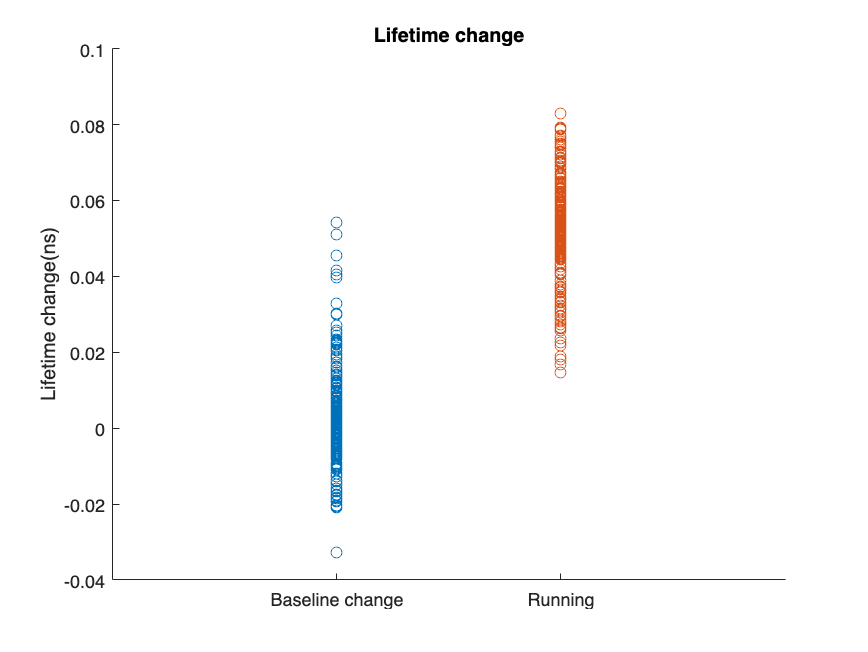


figure
scatter(zeros(1, length(baseline_change_pooled_lft))+1, baseline_change_pooled_lft)
hold on
scatter(zeros(1, length(baseline_change_pooled_lft))+2, running_change_pooled_lft)
xlim([0 3])
xticks([1 2])
xticklabels({'Baseline change', 'Running'})
ylabel('Lifetime change(ns)')
title('Lifetime change')

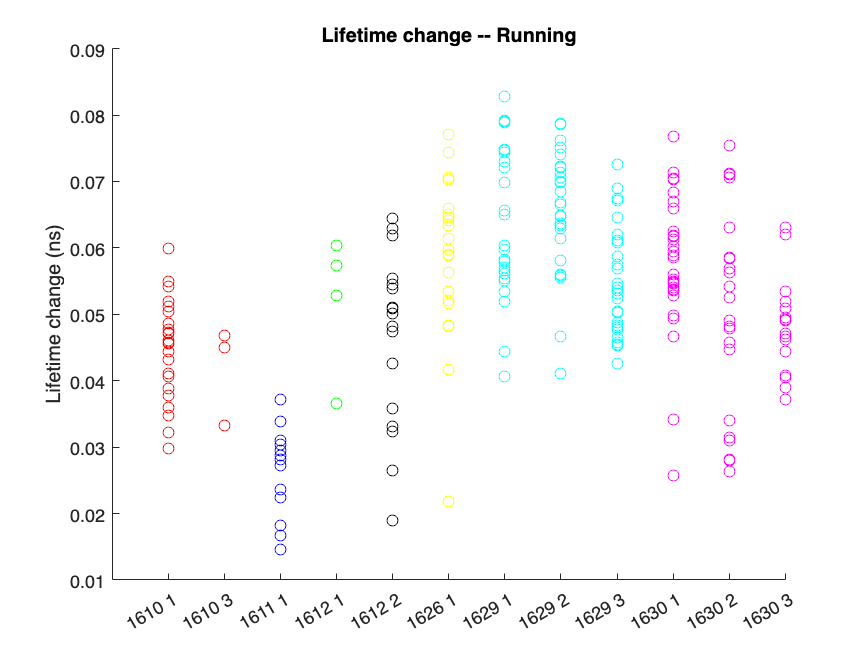

plot_order_animals = [1 7 2 3 8 6 4 9 10 5 11 12];
plot_color_animals = {'r', 'r', 'b', 'g', 'k', 'y', 'c', 'c', 'c', 'm', 'm', 'm'};

figure

for i = 1:12
    scatter(zeros(1, length(median_running_all{plot_order_animals(i)}))+i, median_running_all{plot_order_animals(i)} - median_baselineEnd_all{plot_order_animals(i)}, plot_color_animals{i})
    hold on
end

xlim([0 12])
xticks([1:1:12])
xticklabels(x_tick_labels_animals)
ylabel('Lifetime change (ns)')
title('Lifetime change -- Running')

hold off

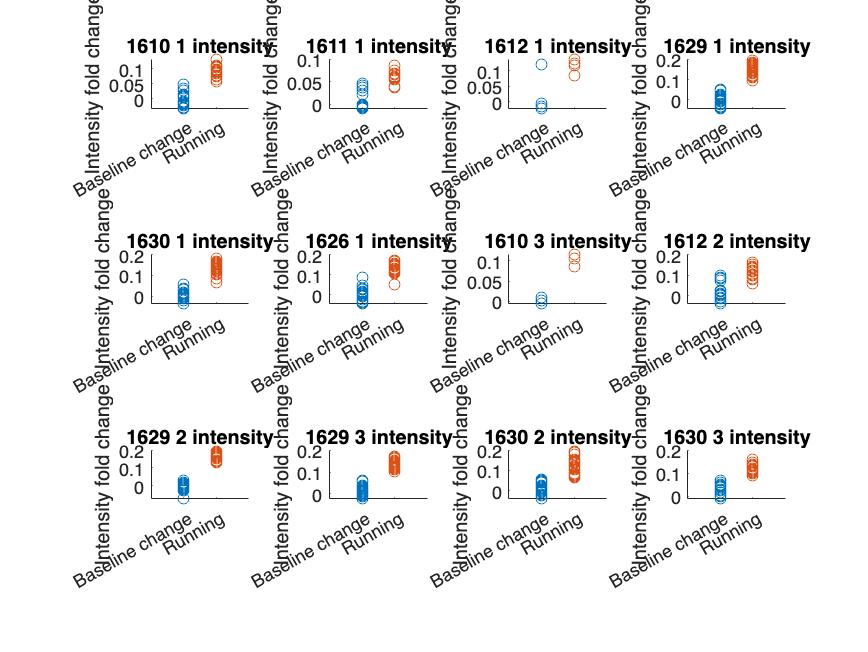

baseline_change_intensity_pooled = [];
running_change_intensity_pooled = [];
baseline_change_intensity_nested = NaN(50,1);
running_change_intensity_nested = NaN(50,1);

for i = 1:12
     subplot(3,4,i)
%     figure
    baseline_intensity_change_this_recording = (median_baselineEnd_intensity_all{i} - median_baselineStart_intensity_all{i})./median_baselineStart_intensity_all{i};
    scatter(zeros(1, length(median_running_intensity_all{i}))+1, baseline_intensity_change_this_recording)
    baseline_change_intensity_pooled = [baseline_change_intensity_pooled baseline_intensity_change_this_recording];
    baseline_change_intensity_nested(1:length(baseline_intensity_change_this_recording), i) = baseline_intensity_change_this_recording';

    hold on
    running_intensity_change_this_recording = (median_running_intensity_all{i} - median_baselineEnd_intensity_all{i})./median_baselineEnd_intensity_all{i};
    scatter(zeros(1, length(median_running_intensity_all{i}))+2, running_intensity_change_this_recording)
    running_change_intensity_pooled = [running_change_intensity_pooled running_intensity_change_this_recording];
    running_change_intensity_nested(1:length(running_intensity_change_this_recording), i) = running_intensity_change_this_recording';
    xlim([0 3])
    xticks([1 2])
    xticklabels({'Baseline change', 'Running'})
    ylabel('Intensity fold change')
    title([animals{i}, ' ', lasers{i}, ' intensity'])
    hold off
end

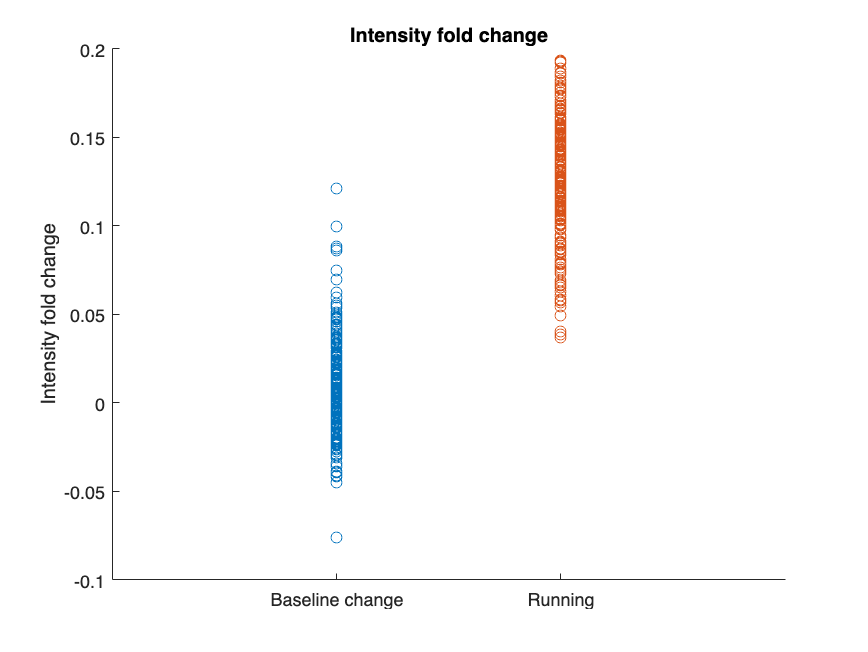


figure
scatter(zeros(1, length(baseline_change_intensity_pooled))+1, baseline_change_intensity_pooled)
hold on
scatter(zeros(1, length(running_change_intensity_pooled))+2, running_change_intensity_pooled)
xlim([0 3])
xticks([1 2])
xticklabels({'Baseline change', 'Running'})
ylabel('Intensity fold change')
title('Intensity fold change')

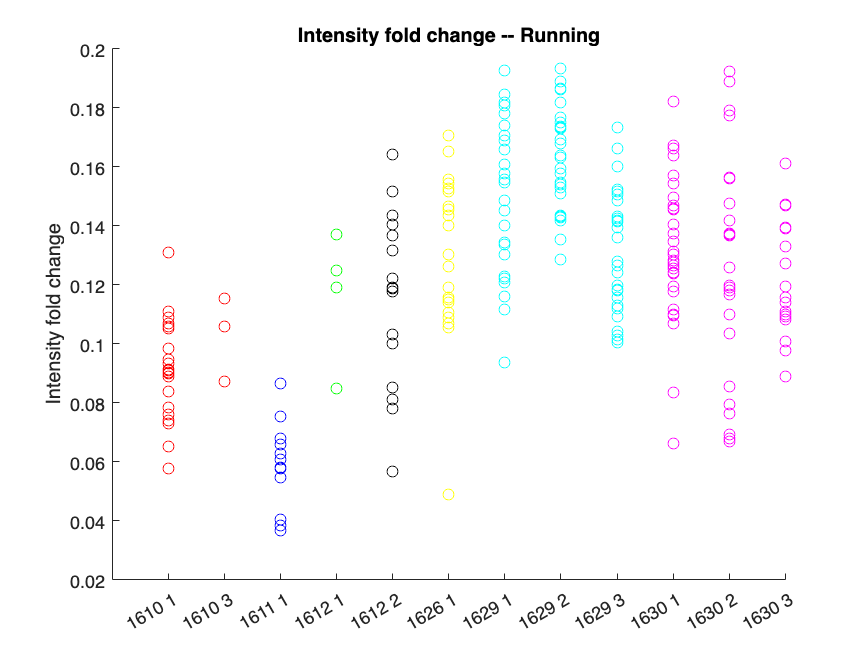

plot_order_animals = [1 7 2 3 8 6 4 9 10 5 11 12];
plot_color_animals = {'r', 'r', 'b', 'g', 'k', 'y', 'c', 'c', 'c', 'm', 'm', 'm'};
x_tick_labels_animals = {};
for i = 1:12
    x_tick_labels_animals{i} = x_tick_labels{plot_order_animals(i)};
end

figure


for i = 1:12
    scatter(zeros(1, length(median_running_intensity_all{plot_order_animals(i)}))+i, (median_running_intensity_all{plot_order_animals(i)} - median_baselineEnd_intensity_all{plot_order_animals(i)})./median_baselineEnd_intensity_all{plot_order_animals(i)}, plot_color_animals{i})
    hold on
end

xlim([0 12])
xticks([1:1:12])
xticklabels(x_tick_labels_animals)
ylabel('Intensity fold change')
title('Intensity fold change -- Running')

hold off

save('Epoch_analysis.mat')

load('Epoch_analysis.mat')

lft_running=lft(find(States==1));
lft_resting=lft(find(States==0));

intensity_running=intensity(find(States==1));
intensity_resting=intensity(find(States==0));

% organize: all lasers of the same mouse
for i = 1:6
    mouse=convertStringsToChars(cell2mat(mouse_all(i)));
    mouse_intensity_AllLaser = NaN(3,100);
    mouse_lft_AllLaser = NaN(3,100);

    for j = 1:3

        eval(['intensity_this_mousepower_resting = intensity_', mouse, '_', num2str(j),'_resting;'])
        eval(['intensity_this_mousepower_running = intensity_', mouse, '_', num2str(j),'_running;'])
        eval(['lft_this_mousepower_resting = lft_', mouse, '_', num2str(j),'_resting;'])
        eval(['lft_this_mousepower_running = lft_', mouse, '_', num2str(j),'_running;'])

        if isempty(intensity_this_mousepower_resting) == 0
            mouse_intensity_AllLaser(j,1:length(intensity_this_mousepower_resting)) = intensity_this_mousepower_resting;
            mouse_intensity_AllLaser(j,51:50+length(intensity_this_mousepower_running)) = intensity_this_mousepower_running;
            mouse_lft_AllLaser(j,1:length(lft_this_mousepower_resting)) = lft_this_mousepower_resting;
            mouse_lft_AllLaser(j,51:50+length(lft_this_mousepower_running)) = lft_this_mousepower_running;
        end
    end

    eval(['a_', mouse, '_intensity_AllLaser = mouse_intensity_AllLaser;'])
    eval(['a_', mouse, '_lft_AllLaser = mouse_lft_AllLaser;'])
end

% organize: all mice of the same laser
for i = 1:3
    
    power = ['power',num2str(i)];
    laser_intensity_AllMice = NaN(7,100);
    laser_lft_AllMice = NaN(7,100);

    for j = 1:6
        mouse=convertStringsToChars(cell2mat(mouse_all(j)));

        eval(['intensity_this_mousepower_resting = intensity_', mouse, '_', num2str(i),'_resting;'])
        eval(['intensity_this_mousepower_running = intensity_', mouse, '_', num2str(i),'_running;'])
        eval(['lft_this_mousepower_resting = lft_', mouse, '_', num2str(i),'_resting;'])
        eval(['lft_this_mousepower_running = lft_', mouse, '_', num2str(i),'_running;'])

        if isempty(intensity_this_mousepower_resting) == 0
            laser_intensity_AllMice(j,1:length(intensity_this_mousepower_resting)) = intensity_this_mousepower_resting;
            laser_intensity_AllMice(j,51:50+length(intensity_this_mousepower_running)) = intensity_this_mousepower_running;
            laser_lft_AllMice(j,1:length(lft_this_mousepower_resting)) = lft_this_mousepower_resting;
            laser_lft_AllMice(j,51:50+length(lft_this_mousepower_running)) = lft_this_mousepower_running;
        end
    end

    eval(['b_', power, '_intensity_AllMice = laser_intensity_AllMice;'])
    eval(['b_', power, '_lft_AllMice = laser_lft_AllMice;'])
end

% organize: pool all lasers and all mice together in nested format
c_intensity_resting_all = [];
c_intensity_running_all = [];
c_lft_resting_all = [];
c_lft_running_all = [];

for i = 1:6
    mouse=convertStringsToChars(cell2mat(mouse_all(i)));
    c_intensity_resting = [];
    c_intensity_running = [];
    c_lft_resting = [];
    c_lft_running = [];

    for j = 1:3
        eval(['c_intensity_resting = [c_intensity_resting; intensity_', mouse, '_', num2str(j), '_resting];' ])
        eval(['c_intensity_running = [c_intensity_running; intensity_', mouse, '_', num2str(j), '_running];' ])
        eval(['c_lft_resting = [c_lft_resting; lft_', mouse, '_', num2str(j), '_resting];' ])
        eval(['c_lft_running = [c_lft_running; lft_', mouse, '_', num2str(j), '_running];' ])
    end

    eval(['c_' mouse, '_intensity_resting = c_intensity_resting;'])
    eval(['c_' mouse, '_intensity_running = c_intensity_running;'])
    eval(['c_' mouse, '_lft_resting = c_lft_resting;'])
    eval(['c_' mouse, '_lft_running = c_lft_running;'])

    c_intensity_resting_all = [c_intensity_resting_all c_intensity_resting];
    c_intensity_running_all = [c_intensity_running_all c_intensity_running];
    c_lft_resting_all = [c_lft_resting_all c_lft_resting];
    c_lft_running_all = [c_lft_running_all c_lft_running];
end

% plot speed and lifetime trace
i = 5;
analysis_file_name = [datapath_all{i}, ExperimentalName_all{i}, '_analysis_1_', analysis_postfix{i}]

analysis_file_name = '/Volumes/PcSSDA/RvR/20220328_1630_RvR_001/20220328_1630_RvR_001_analysis_1_20220512.mat'

load(analysis_file_name)
time =  time - Speed_time_shift_all(i);
time_of_speed_seconds = Time_all{i};
speed = Speed_all{i};


figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


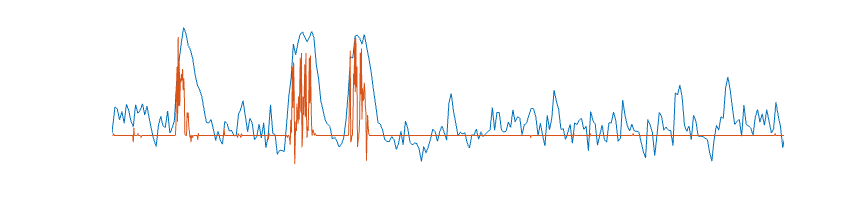

yyaxis left
plot(time,tau_empTrunc);
ylabel('Lifetime (ns)','FontSize',24)
ylim([4.16 4.26])
yticks([4.15 4.20 4.25 4.3])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-5 20])
yticks([-10 0 10 20])
xlim([0 300])
xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
% title('Intensity', 'FontSize',24, 'Color', 'b')
% legend('Lifetime','Speed','FontSize',20)
box off
axis off

% title([mouse ' ' Recording])


figure2=figure;
figure2.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


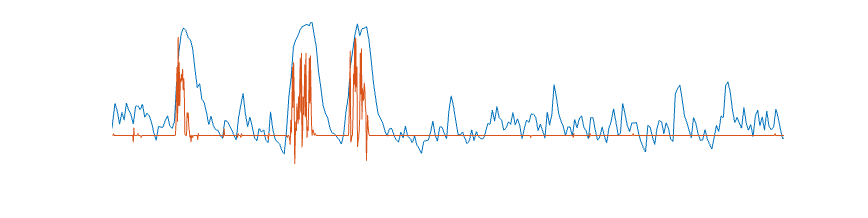

yyaxis left
plot(time,photoncount);
ylabel('Intensity','FontSize',24)
ylim([550000 670000])
yticks([550000 600000 650000])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-5 20])
yticks([-10 0 10 20])
xlim([0 300])
xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
% legend('Intensity','Speed','FontSize',20)
box off
axis off

% title([mouse ' ' Recording])

speed_min = min(speed(find(time_of_speed_seconds <= 300)))

speed_min = -5.6282

speed_max = max(speed(find(time_of_speed_seconds <= 300)))

speed_max = 17.2868

plot_height = 36.5892

plot_height = 36.5892


(plot_height/(speed_max - speed_min))*20

ans = 31.9347

intensity_min = min(photoncount(find(time <= 300)))

intensity_min = 558196

intensity_max = max(photoncount(find(time <= 300)))

intensity_max = 671488

plot_height_intensity = 37.6091

plot_height_intensity = 37.6091


(plot_height_intensity/(intensity_max - intensity_min))*40000

ans = 13.2786

lft_min = min(tau_empTrunc(find(time <= 300)))

lft_min = 4.1617

lft_max = max(tau_empTrunc(find(time <= 300)))

lft_max = 4.2559

plot_height_lft = 37.6869

plot_height_lft = 37.6869


(plot_height_lft/(lft_max - lft_min))*0.03

ans = 12.0003

function NearestIndex = FindNearestIndex(TimeArray, TimePoint)
        time_diff = abs(TimeArray - TimePoint);
        NearestIndex = find(time_diff == min(time_diff));
end

function [median_index, median_plot] = FindMedianIndex(data, start_index)
        [med,I]=sort(data);

        if rem(size(data),2)==1
            median_index =I((size(data,1)+1)/2)+start_index-1;
            median_plot = median(data);
        else
            median_index = [I(size(data,1)/2) I(size(data,1)/2+1)]+start_index-1;
            median_plot = [median(data) median(data)];
        end
        

end